clear; clc;

## Exercise 3.4

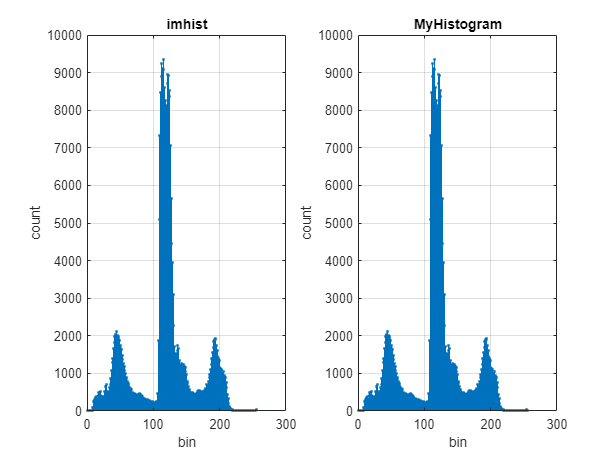

% The im2gray function is identical to rgb2gray except that it can accept grayscale images as inputs, returning them unmodified. The rgb2gray function returns an error if the input image is a grayscale image. If you use the im2gray function, code like this loop is no longer necessary.
% https://au.mathworks.com/help/matlab/ref/im2gray.html#mw_b4fbc85d-d8ff-40b0-97c3-f00ec7fc2429

% img = rgb2gray(imread('landscape.bmp'));
img = im2gray(imread('landscape.bmp'));

figure
subplot(1,2,1)
[h, x] = imhist(img, 256); % compute histogram with 256 bins
stem(x, h, '.'); % plot the histogram
grid, xlabel('bin'), ylabel('count')
title('imhist');	

subplot(1,2,2)
[h, x] = MyHistogram(img,256); % compute histogram with 256 bins
stem(x, h, '.'); % plot the histogram
grid, xlabel('bin'), ylabel('count')
title('MyHistogram');

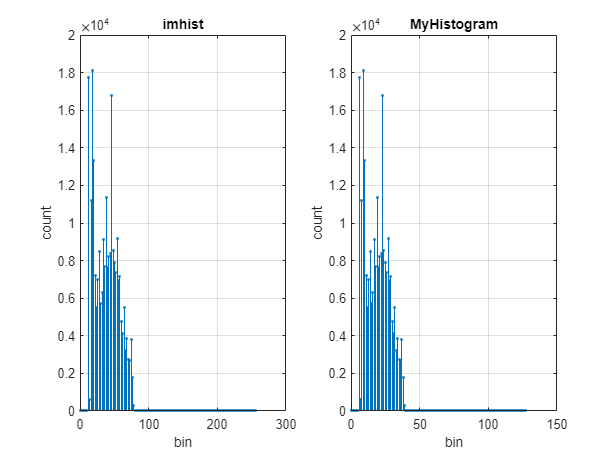

% img = rgb2gray(imread('pollen.tif'));
img = im2gray(imread('pollen.tif'));

figure
subplot(1,2,1)
[h, x] = imhist(img, 128); % compute histogram
stem(x, h, '.'); % plot the histogram
grid, xlabel('bin'), ylabel('count')
title('imhist');	

subplot(1,2,2)
[h, x] = MyHistogram(img,128); % compute histogram
stem(x, h, '.'); % plot the histogram
grid, xlabel('bin'), ylabel('count')
title('MyHistogram');

Function

function [image_histogram_h, grayLevels] = MyHistogram(grayImage, L)

% Linear Streching to scale gray levels
low_in		= 0;
high_in		= 255;
low_out		= 0;
high_out	= L-1;
grayImage = imadjust(grayImage, [low_in high_in]/255, [low_out high_out]/255, 1);

% Scale gray image to L levels
% grayImage = grayImage/(256/L);


% [rows, columns, numberOfColorChannels] = size(grayImage);
[rows, columns, ~] = size(grayImage);

% % To compute image histogram for other bin sizes such as 128 or 64, how should your program be modified?
%   if nargin < 2
%     L = 256;x
%   end
% % 
% 
% disp(L);


image_histogram_h = zeros(1, L);
for col = 1 : columns
	for row = 1 : rows
		% Get the gray level.
		grayLevel = (grayImage(row, col));
		% Add 1 because graylevel zero goes into index 1 and so on.
		image_histogram_h(grayLevel+ 1) = image_histogram_h(grayLevel+1) + 1;
	end
end
grayLevels = 0 : L-1;
end